# MATLAB tutorial for the analysis of neural signals

## 1. Introduction to tutorial

### 1.1 Objectives 

This tutorial aims to help neuroscientists do some basic neural signal processing and analysis using MATLAB. For neuroscientists, processing neural signals is an important step when studying the electrical discharges of nerve cells - a field known as **electrophysiology**. After this tutorial, one should be able to

- Create a basic signal processing workflow for electrophysiology data in MATLAB

- Visualize and analyze neural signals using the [Signal Analyzer App](https://www.mathworks.com/help/signal/ref/signalanalyzer-app.html)

- Use [timetables](https://www.mathworks.com/help/matlab/timetables.html) when dealing with time resolved data

- [Design filters ](https://www.mathworks.com/discovery/filter-design.html)

- Use [frequency domain analyses](https://www.mathworks.com/help/matlab/math/basic-spectral-analysis.html) such as [power spectrum](https://www.mathworks.com/help/signal/ref/pspectrum.html) calculations and [time frequency plots](https://www.mathworks.com/help/signal/time-frequency-analysis.html?category=time-frequency-analysis&s_tid=CRUX_topnav)

- Combine analysis and results together into a [Live Script](https://www.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html) for presentation (lab meetings, conferences)

To be able to run this tutorial, the [Signal Processing Toolbox](https://www.mathworks.com/products/signal.html) and the [Statistics and Machine Learning Toolbox](https://www.mathworks.com/products/statistics.html) are required. If there is no MATLAB license available, a free trial here can be [downloaded here](https://www.mathworks.com/campaigns/products/trials.html).

### 1.2 Further learning

Additional resources related to neuroscience applications with MATLAB 

-  The MathWorks [Neuroscience](https://www.mathworks.com/solutions/neuroscience.html) page including the section on [tools](https://www.mathworks.com/solutions/neuroscience/resources.html). 

-  For signal processing fundamentals, the self-paced [Signal Processing OnRamp](https://www.mathworks.com/learn/tutorials/signal-processing-onramp.html) from MathWorks. 

-  Latest features in MATLAB suited for[ neural and biosignal analysis](https://www.mathworks.com/solutions/neuroscience/latest-features.html)

-  More material and related exercises in the books [MATLAB for Neuroscientists](https://www.amazon.com/MATLAB-Neuroscientists-Introduction-Scientific-Computing/dp/0123838363/ref=sr_1_1?crid=129ZX09LJQSYP&dchild=1&keywords=matlab+for+neuroscientists&qid=1608231902&sprefix=MATLAB+for+ne%2Caps%2C255&sr=8-1) and [Signal Processing for Neuroscientists](https://www.amazon.com/Signal-Processing-Neuroscientists-Introduction-Physiological-ebook/dp/B00AQ47LCK/ref=sr_1_2?crid=XGLZ4C9MXZSU&dchild=1&keywords=signal+processing+for+neuroscientists&qid=1608231868&sprefix=signal+proceesing+for+neuroscien%2Caps%2C326&sr=8-2)

### 1.3 Topics covered

This tutorial implements several standard steps in experimental electrophysiology used by many neuroscientists. These include

- Reading in a neural signal

- Visualizing the signal

- Filtering the signal into high (spikes)- and low frequency (local field potential, LFP) bands 

- Extracting spikes from the high frequency signal 

- Sorting spike waveforms using principal component analysis and Gaussian mixed model clustering

- Calculating the power spectrum of the low frequency band

- Calculating a periodogram (time frequency plots) for the low frequency band

Functions used: [*timetable*](https://www.mathworks.com/help/matlab/ref/timetable.html?searchHighlight=timetable&s_tid=srchtitle)*, *[*butter*](https://www.mathworks.com/help/signal/ref/butter.html?searchHighlight=butter&s_tid=srchtitle)*, *[*filtfilt*](https://www.mathworks.com/help/signal/ref/filtfilt.html?searchHighlight=filtfilt&s_tid=srchtitle)*, *[*findpeaks*](https://www.mathworks.com/help/signal/ref/findpeaks.html?searchHighlight=findpeaks&s_tid=srchtitle)*, *[*pca*](https://www.mathworks.com/help/stats/pca.html?searchHighlight=pca&s_tid=srchtitle)*, *[*fitgmdist*](https://www.mathworks.com/help/stats/fitgmdist.html)*, *[*cluster*](https://www.mathworks.com/help/stats/gmdistribution.cluster.html?searchHighlight=cluster&s_tid=srchtitle)*, *[*histogram*](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html?searchHighlight=histogram&s_tid=srchtitle)*, *[*fft*](https://www.mathworks.com/help/matlab/ref/fft.html?searchHighlight=fft&s_tid=srchtitle)*, *[*pspectrum*](https://www.mathworks.com/help/signal/ref/pspectrum.html?searchHighlight=pspectrum&s_tid=srchtitle)*, *[*spectrogram*](https://www.mathworks.com/help/signal/ref/spectrogram.html?searchHighlight=spectrogram&s_tid=srchtitle)

## 2. Background and key concepts

The nervous system is made up of neurons which contain dendrites, a cell body or soma and an axon. The neuron has a ***resting membrane potential*** which is negative compared to the extracellular fluid. Excitatory impulses from neighboring neurons produce small transient positive voltage fluctuations (***depolarizations***) at the dendrites. If the sum of these depolarizations exceeds a certain threshold, certain ion channels open within the neural membrane and positively charged ions (Na+, Ca++) rush inside to temporarily reverse the negative membrane potential resulting in a positive ***action potential***. Action potentials are colloquially referred to as ***spikes***. For a MATLAB tutorial on simulating spiking neurons according to the very well-known Izhikevich model [1], see [here](https://www.mathworks.com/matlabcentral/fileexchange/86198-live_script_spiking_neurons?s_tid=srchtitle).

There are several types of electrophysiological signals neuroscientists commonly record. These can be EEG, ECoG, LFP, extracellular and intracellular recordings in order of increasing invasiveness and signal specificity. The most specific signal is the intracellular recording where the experimenter records from within one single cell. However, with each level of specificity the experimenter samples progressively smaller spatial extents of neural tissue. *All these signals are neural signals and can be analyzed using some of the steps shown in this tutorial.*

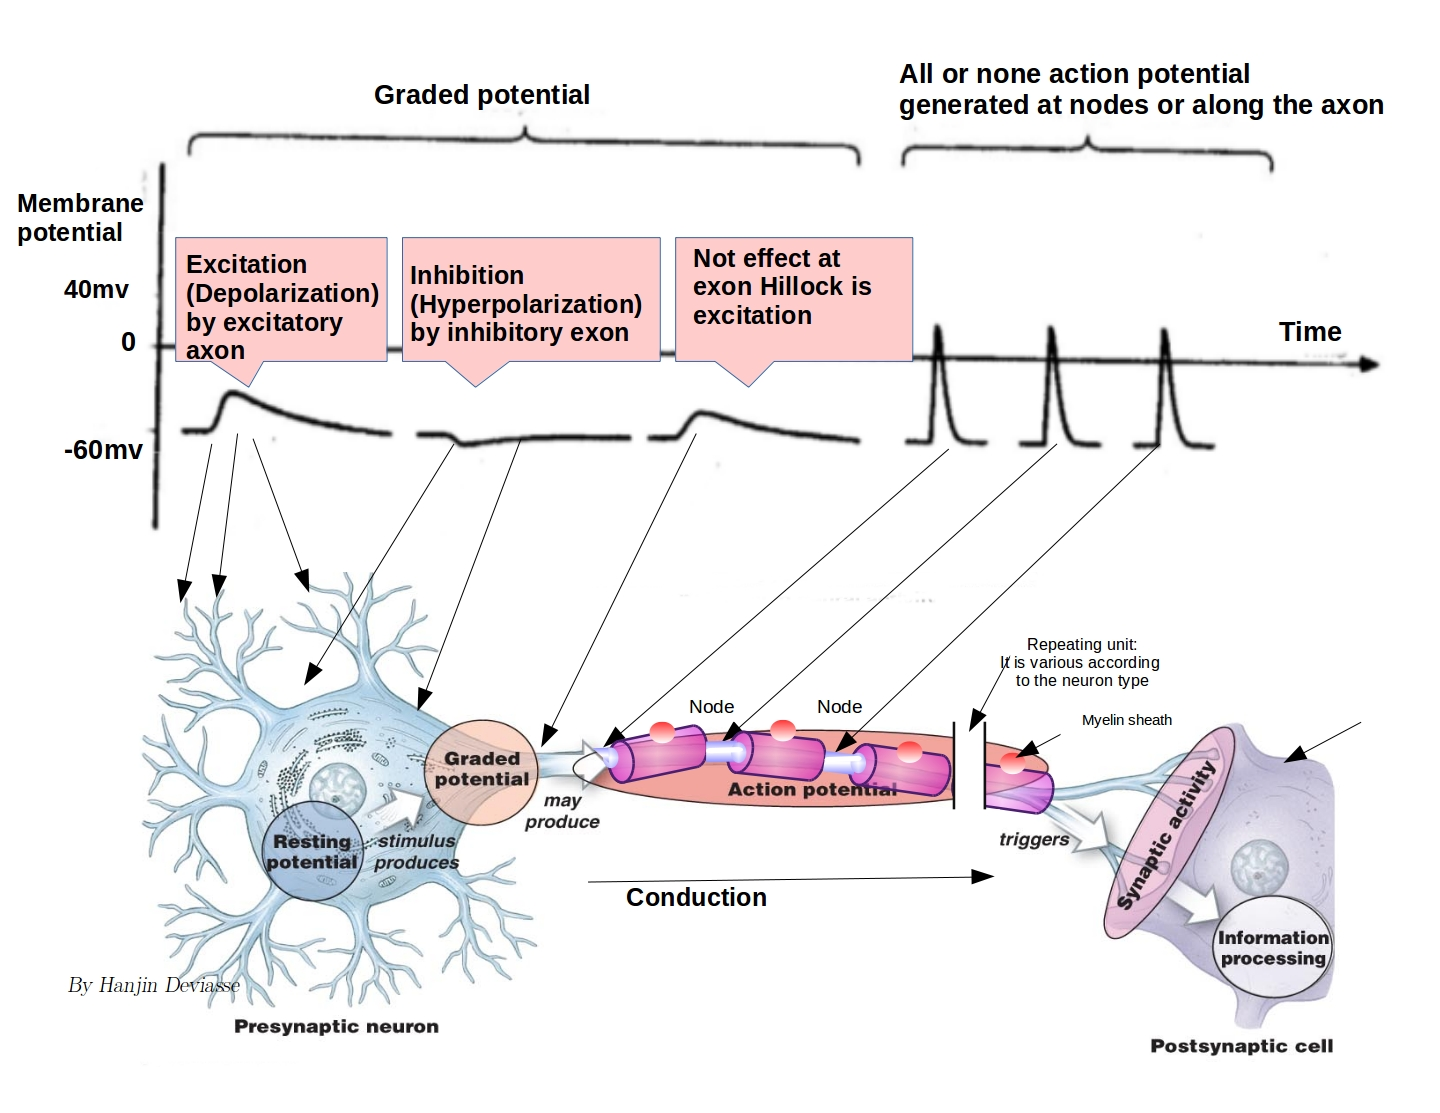

*Depolarizing potentials in the dendrites lead to action potentials in the soma. Image courtesy: *[2]  

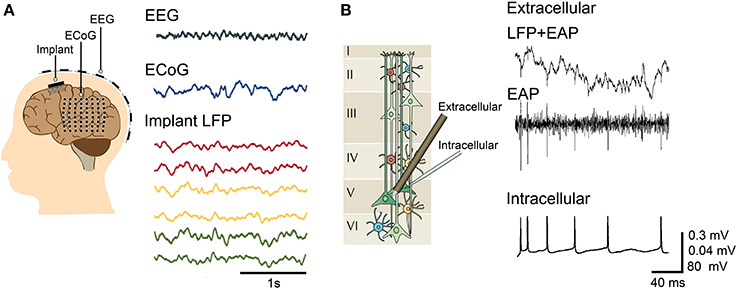

* The different electrophysiological signals that are commonly recorded by neuroscientists. Image courtesy: *[3]. *Includes content originally from Buzsaki lab [4], [5]. *

### 2.1 Standard steps in electrophysiology data analysis for neuroscientists

Placing an electrode inside the brain or neural tissue enables the neuroscientist to record the action potential discharged by neighboring neurons with respect to a reference electrode. The placement of the reference electrode determines if signals are recorded from a small region (reference electrode adjacent to recording electrode; ideal for recording spikes) or from a large region (reference electrode far away from recording electrode; ideal for recording LFP's). Additionally spikes are high frequency events (duration approx 600 µs) whereas LFP's are low frequency signals, often capturing the sub-threshold potential fluctuations at slow time scales.

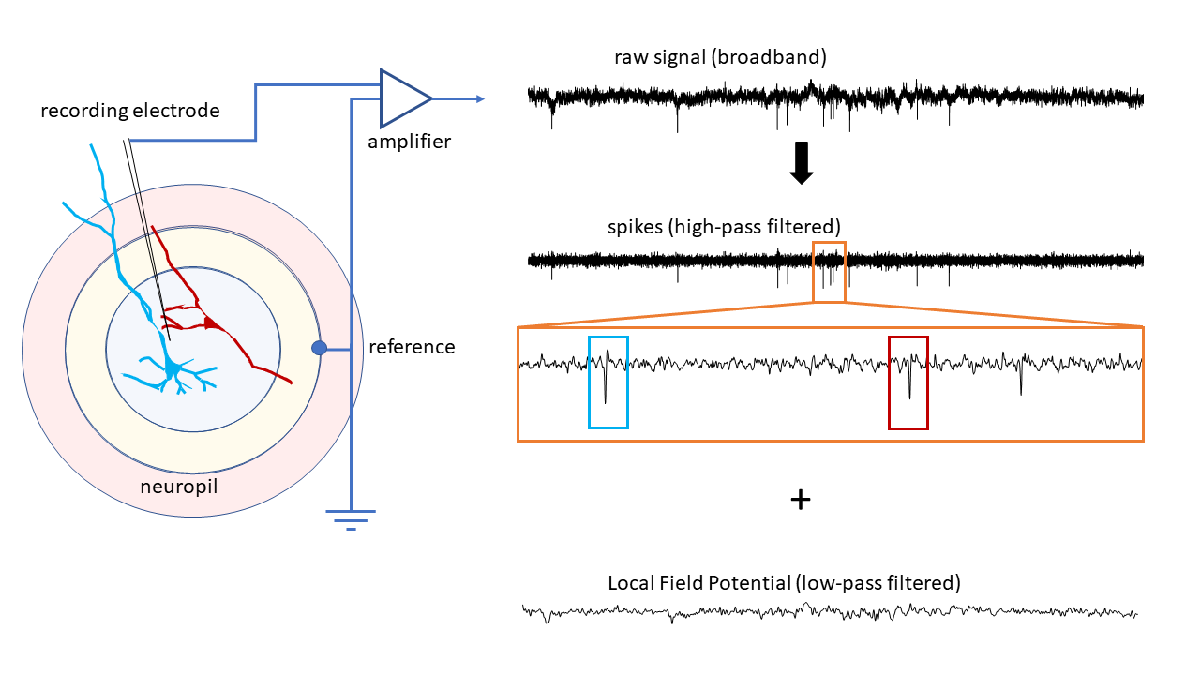

*Demonstration of the basic electrophysiology data acquisition setup for neuroscientists. The recording electrode is inserted into the neuropil adjacent to several neurons. The reference electrode is placed somewhere in the neuropil. The closer the reference is to the recording electrode, the smaller is the electrical field from which signals are recorded. The raw signal is amplified and digitized at a desired sampling frequency. Filtering of the raw signal yields two components. A high pass filtered component (~500Hz upwards) is ideal for extracting and isolating spikes. Spikes from several different neurons (indicated by colored boxes) might be recorded using the same electrode and need to be separated later (spike extraction and sorting). Spike analysis is typically restricted to the time domain. A low pass filtered component is ideal for analysing LFPs which carry information about subthreshold inputs and global oscillations. LFP analyses are typically in the frequency domain. Image courtesy: Shubo Chakrabarti.*

### 2.2 Nyquist law and sampling frequency

It is important to know that the sampling frequency (the frequency with which the analog signal is digitized) should be at least twice the largest frequency present in the data. If the data contains frequencies upto 250 Hz, a sampling frequency of 500 Hz (500 points digitized within one second) is required. This is known as **Nyquist Law**. Since action potentials (spikes) are high frequency events with a total duration of <1ms, neural signals are sampled at a sampling frequency of at least 10kHz. A/D boards for electrophysiology have adjustable sampling frequencies. 

To empirically test this in MATLAB, we will create two sine waves one having a frequency of 2Hz and one of 10Hz. We will sample both with a sampling frequency of 5Hz. Sine waves are defined by the equation $y=\sin \left(2*\textrm{pi}*f*x\right)$

fsExample = 33; % sampling frequency
x = 0:1/fsExample:1-1/fsExample; % time axis (sampling)
sine1 = sin(2*pi*2*x); % sine wave of 2 Hz
sine2 = sin(2*pi*10*x); % sine wave of 10 Hz


Create a highly sampled signal for reference

CompareAgainstTrueSignals = true;
if CompareAgainstTrueSignals
    fs_control = 1000;
    x_control = 0:1/fs_control:1-1/fs_control;
    sine1_control = sin(2*pi*2*x_control); % sine wave of 2 Hz
    sine2_control = sin(2*pi*10*x_control);
end


Plot signals 

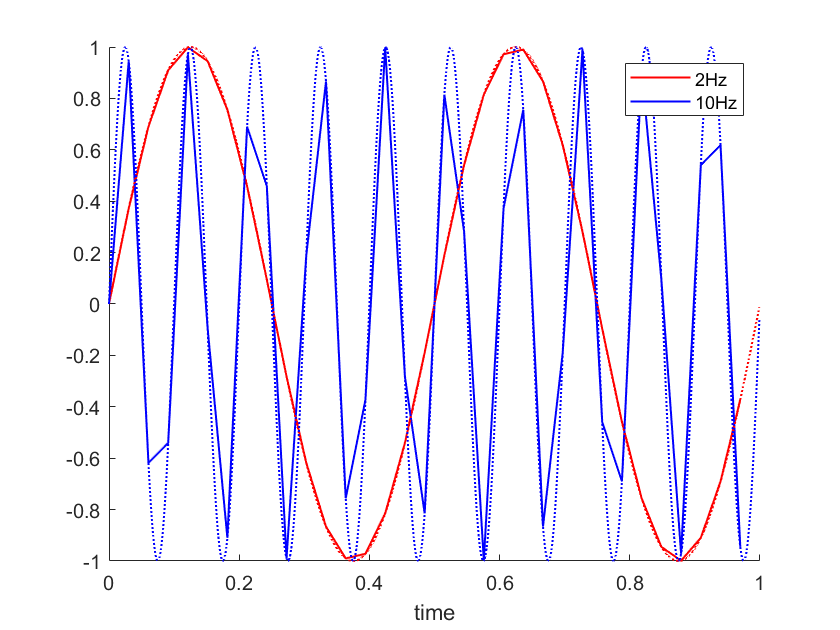

figure; hold on
plot(x,sine1,'r','LineWidth',1);
plot(x,sine2,'b','LineWidth',1);
if CompareAgainstTrueSignals
    plot(x_control,sine1_control,':r','LineWidth',1);
    plot(x_control,sine2_control,':b','LineWidth',1);
end
xlabel('time');
legend('2Hz','10Hz')

## 3. Data pre-processing and analysis steps

### 3.1 Reading in the data

It is possible to read in different types of data directly into MATLAB. A list of datatypes (both scientific and common data formats) can be found[ here](https://www.mathworks.com/help/matlab/import_export/supported-file-formats.html). 

For neuroscientists, a number of specialized data formats such as [BIDS](https://github.com/bids-standard/bids-matlab), [NeurodatawithoutBorders](https://github.com/NeurodataWithoutBorders/matnwb), [NIfTI](https://www.mathworks.com/help/images/ref/niftiread.html), [EDF](https://www.mathworks.com/help/signal/ref/edfread.html) have MATLAB support. Many [standard vendors](https://www.mathworks.com/products/connections/search-products.html?q=&fq=marketing-industry:neuroscience&page=1) offer dedicated function libraries for accessing their data in MATLAB. 

For this exercise, we will use a dataset recorded from the rodent somatosensory cortex [6] using glass insulated tungsten electrodes. The dataset is saved under the name *neural_data.mat* and contains two variables, *data* (vector) and *fs* (scalar). The fs denotes the sampling frequency which was 40kHz.

Data contains voltage signals digitized by an analog-digital converter at every step. fs is the sampling frequency. It tells us how many times, within a second, the analog signal from the electrode was digitized. 

Load the data onto MATLAB

clearvars
load('neural_data.mat')

### 3.2 Converting the data into a timetable

Next, we are going to convert the signal into a [timetable](https://www.mathworks.com/help/matlab/timetables.html?s_tid=CRUX_lftnav) variable. Timetables are ideal for values sampled evenly at a certain time interval. Time and data values can be stored in one variable.

neural = timetable(data,'SampleRate',fs);
neural.Properties.VariableNames{1} = 'raw';
neural.Properties.VariableUnits{1} = 'Volts';

### 3.3 Visualizing the signal

First we shall plot the signal to visually inspect it. Often the first visual inspections yield a lot of information about the data. Even if later steps are to be automatized, the initial exploratory phase of any data analysis workflow should begin by visualizing selected samples of data collected, to answer some basic questions such as

- Are there low/high frequencies in the data

- Are there artefacts in the data

At this point let us plot the signal against a time axis. We will use the sampling frequency to construct a vector of time stamps.

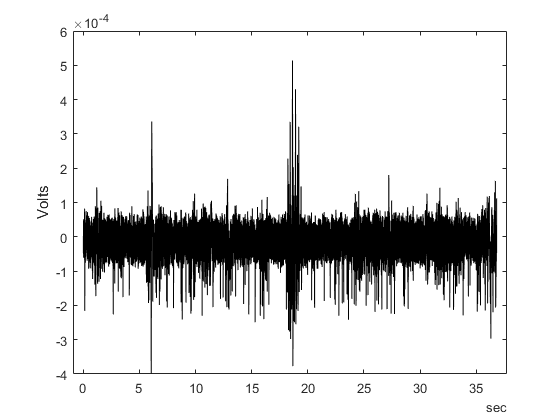

figure;
plot(neural.Time,neural.raw,'k')
ylabel(neural.Properties.VariableUnits(strcmpi(neural.Properties.VariableNames,'raw'))) % query variable name and units

There are a few things we can see from this signal

- There are some occasional high frequency oscillations 

- There are slow oscillations (low frequency) throughout 

- There is an obvious artefact occuring around 6 seconds into the recording

MATLAB offers another click-and-point method for visualizing signals and analyzing signals via the [Signal Analyzer App](https://www.mathworks.com/help/signal/ref/signalanalyzer-app.html) from the Apps toolbar

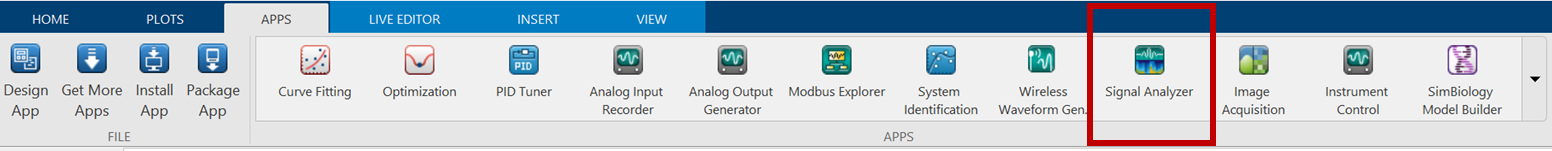

Signal Analyzer offers a interactive way to visualize, pre-process, measure, analyze and compare signals. 

### 3.4 Separating the neural signal into spikes and field potentials

The signal from an electrode has both low and high frequency components. To separate these two components, we need to separate the signals in the frequency domain using filters. There are several [filtering capabilities](https://www.mathworks.com/discovery/filter-design.html) in MATLAB. For the purposes of this tutorial we will use a simple [Butterworth filter](https://www.mathworks.com/help/signal/ref/butter.html). A Butterworth filter is an IIR filter which shifts the signal in phase and therefore has causal effects on the signal. To prevent this, we use the [filtfilt](https://www.mathworks.com/help/signal/ref/filtfilt.html) function which filters the signal in both directions to cancel out the effect of this phase shift called [zero-phase filtering](https://www.mathworks.com/help/signal/ref/filtfilt.html?searchHighlight=filtfilt&s_tid=srchtitle).

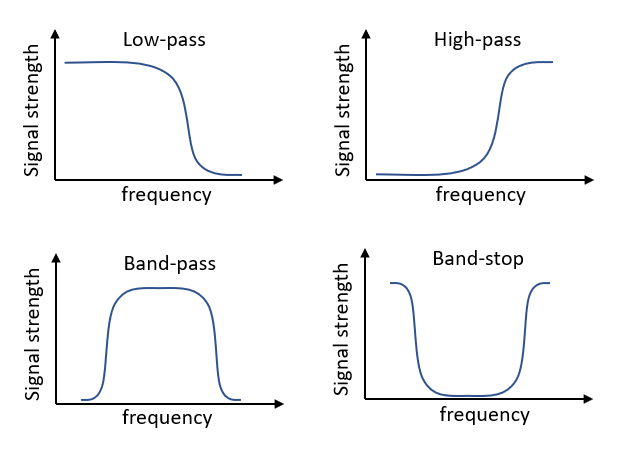

*Schematic demonstrating the effects of high and lowpass, bandpass and bandstop filters. The x axis represents frequency and the y axis the power. Image Courtesy: Philip Laserstein*

The experimenter needs to decide the cutoff frequencies for filtering. There is no current answer here as the cutoff frequencies depend on the signal and the data acquisition conditions (example: electrical noise at 50/60 Hz).

Filtering the raw broadband signal into two parts with a high pass cutoff at 500 and a low pass cutoff at 200 Hz

HighCutOff = 500;
LowCutOff = 200;
[b_high, a_high] = butter(5,HighCutOff/fs,"high"); % filter co-efficients
[b_low, a_low] = butter(5,LowCutOff/fs,"low");
neural.spikes = filtfilt(b_high,a_high,neural.raw); % filter the signals using zero phase filtering
neural.LFP = filtfilt(b_low,a_low,neural.raw);
neural.Properties.VariableUnits(2:3) = {'Volts','Volts'};

Plotting the two signals, spikes and LFPs for comparison

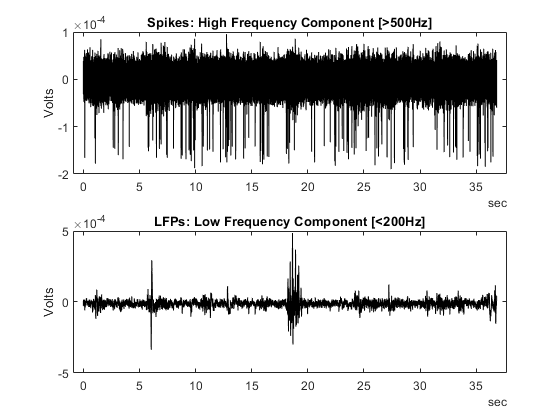

figure;
subplot(2,1,1)
plot(neural.Time,neural.spikes,'k')
ylabel(neural.Properties.VariableUnits(strcmpi(neural.Properties.VariableNames,'spikes')))
title(['Spikes: High Frequency Component [>',num2str(HighCutOff),'Hz]'])
subplot(2,1,2)
plot(neural.Time,neural.LFP,'k')
ylabel(neural.Properties.VariableUnits(strcmpi(neural.Properties.VariableNames,'LFP')))
title(['LFPs: Low Frequency Component [<',num2str(LowCutOff),'Hz]'])

Notice that the artefacts were in the low frequency band (probably caused due to movements).

TODO: Load the neural timetable into Signal Analyzer and display the three signals. Extract a ROI with data cursors

### 3.5 Detecting, extracting and sorting spikes

Now that we have high pass filtered our data, we need to extract the spikes. There are three steps to spike extraction.

- Thresholding and detecting all local minima that exceed this thresold. 

- Extracting snippets of data that contain the spike waveforms. This yields all spike waveforms in the signal (MUA)

- Sorting the extracted spike waveforms into distinct categories. This yields spike waveforms that could come from single neurons (SUA)

#### 3.5.1 Spike detection

Let us start by extracting all minima beyond a certain threshold. To do this, we do a peak detection on the inverse of the signal (find minima) and find instances below a certain threshold

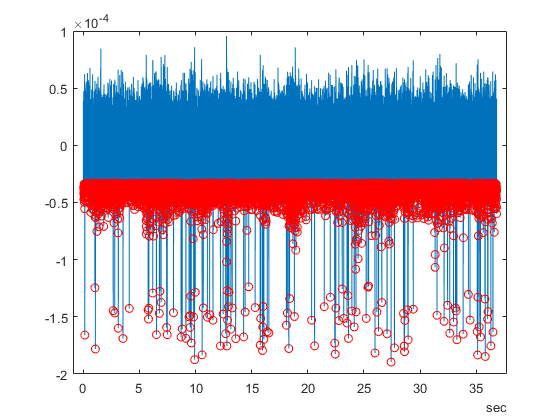

threshold = -0.000033;
[pks,locs] = findpeaks(-neural.spikes,'MinPeakHeight',abs(threshold));
figure
plot(neural.Time,neural.spikes); hold on
line([min(neural.Time) max(neural.Time)],[threshold threshold],'color','r','LineWidth',1)
scatter(neural.Time(locs),-pks,'or'); hold off

#### 3.5.2 Spike extraction

Let us extract a snippet of signal with a certain window centered around the minima of the waveform

prePeak = 0.0005; % length of window to extract before spike peak (s)
posPeak = 0.0005; % length of window to extract after spike peak (s)
prePeakTimes = neural.Time(locs)-seconds(prePeak); % window limits centered on spike minima
posPeakTimes = neural.Time(locs)+seconds(posPeak);
prePeakTimes(prePeakTimes<0) = 0; % trim windows exceeding beyond zero
posPeakTimes(posPeakTimes>max(neural.Time)) = max(neural.Time); % trim windows exceeding beyond signal end


Extracting the spike snippets by looping through window start and stop times

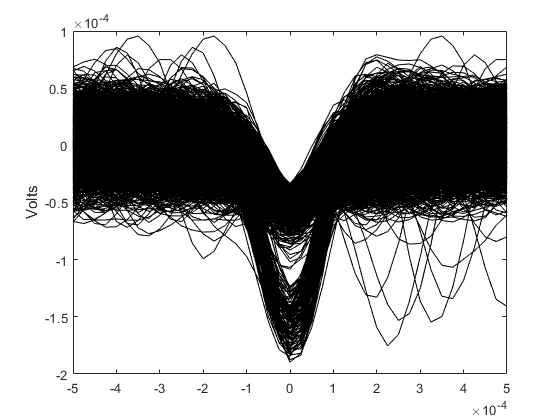

ts = -prePeak:1/fs:posPeak;
spks = zeros(length(locs),length(ts));
for i = 1:length(locs)
    S = timerange(prePeakTimes(i),posPeakTimes(i),'closed');
    spks(i,:) = neural.spikes(S);
end
figure;
plot(ts,spks','k')
ylabel(neural.Properties.VariableUnits(strcmpi(neural.Properties.VariableNames,'spikes'))) % query variable name and units

#### 3.5.3 Spike sorting

As one can see from the above figure, there are two separate waveforms buried in the data, one with a large minima and others with a smaller minima. Since the electrode is placed with a unique spatial relationship to each neuron, spikes from different neurons around the electrode will have different shapes whereas the spikes from the same neuron will probably have very similar shapes. [Spike sorting ](https://www.sciencedirect.com/science/article/pii/S0361923015000684)aims to separate putative discharges from different neurons on the basis of similarities and differences in their recorded waveforms. There are some caveats to remember during spike sorting. 

- A clean, clearly distinguishable spike ultimately depends on an optimal recording electrode (impedances, insulation) being placed effectively.

- All spike sorting methods classify and sort spikes based on their shape. Inferences about them being from the same neuron are assumptions.

- Extracellular neural recordings are non-stationary. This means that a spike can change shape or merge with noise during the recording as the electrode drifts in the tissue.

There are numerous spike sorting algorithms. For freely available and downloadable spike sorting algorithms, one can browse the [MATLAB File Exchange](https://www.mathworks.com/matlabcentral/fileexchange?category%5B%5D=1728&q=spike+sorting)

#### 3.5.4 Principal component analysis 

To sort our waveforms, we will depend on one of the simplest clustering algorithms used - [principal component analysis](https://www.mathworks.com/help/stats/principal-component-analysis-pca.html). Any dataset can be broken down into its principal components. The distribution of the data along each principal component explains some of the variance of the data. Most of the variance can be explained by the first few principal components. One can think of PCA as fitting an ellipsoid envelope to the data. Each axis of the ellipsoid represents a principal component. If the axis is small, the variance along that component is small. Distributions of the data along those principal components which yield maximal variation makes it easier to recognize and separate clusters.

For our example, the spikes are sampled with a fs of 40,000 Hz which means there are 40 sampling points (1ms) in each waveform. This means that each spike could differ in each of these 40 points (dimensions). By using PCA, we [reduce this to the two dimensions](https://www.mathworks.com/help/stats/dimensionality-reduction.html) along which the data shows the maximal variance.

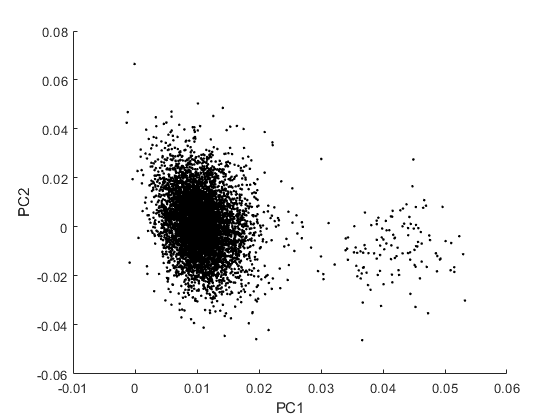

coeff = pca(spks');
figure; 
scatter(coeff(:,1),coeff(:,2),'.k')
xlabel('PC1')
ylabel('PC2')

#### 3.5.5 Gaussian mixture model based clustering

Now we have reduced the 40 dimensional data to two dimensions capturing the maximal variance. This plot clearly shows us two clusters. The next step is to define these clusters and associate all the data points to one of the clusters. 

There are several automatic [clustering algorithms](https://www.mathworks.com/discovery/cluster-analysis.html) and the [gaussian mixture model based clustering](https://www.mathworks.com/help/stats/clustering-using-gaussian-mixture-models.html) is one of them. Let us create a Gaussian model with two components

GMM = fitgmdist(coeff(:,1:3),2,'Start','plus','CovarianceType',"diagonal",'SharedCovariance',true); % fit 2 Gaussian models to the data
idx = cluster(GMM,coeff(:,1:3)); % cluster using the GMM

The next few lines of code are non-essential. They simply make sure the large spike is plotted on top of the noise signal for better visualization

if max(coeff(idx==1,1))>max(coeff(idx==2,1))
    idx2 = idx;
    idx(idx2==2) = 1;
    idx(idx2==1) = 2;
    clear idx2
end

Now let us plot the original PCA cluster and superimpose our cluster labels on them

figure; % re-plot original PCA 
xlabel('PC1'); ylabel('PC2'); axis square; hold on

Toggle between clusters and raw PCA data (non-essential)

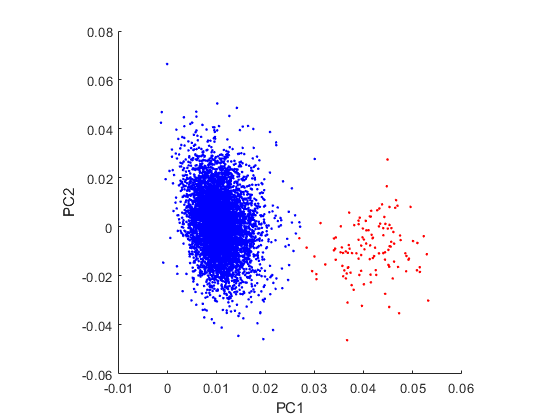

superimposeClusterLabels = true; 
if ~superimposeClusterLabels
    scatter(coeff(:,1),coeff(:,2),'.k')
else
    scatter(coeff(idx==1,1),coeff(idx==1,2),'.b')
    scatter(coeff(idx==2,1),coeff(idx==2,2),'.r')
end

If we now replot our orginal spike waveforms, color-coded for the cluster labels, we can visualize the results of our sorting method

figure;  axis square; hold on % plot the original waveforms
ylabel(neural.Properties.VariableUnits(strcmpi(neural.Properties.VariableNames,'spikes'))) % query variable name and units

Toggle between clustered and raw spikes (non-essential)

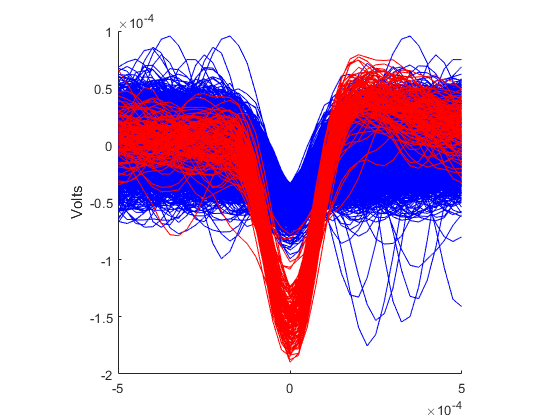

colorCodeWaveformClusters = true; 
if ~colorCodeWaveformClusters
    plot(ts,spks','k');
else
    plot(ts,spks(idx==1,:)','b'); 
    plot(ts,spks(idx==2,:)','r'); 
end

#### 3.5.6 Using cluster labels to plot rasters and the PSTH

Now let us add the cluster indices to the plot to obtain a simple raster and then bin the spikes to obtain a PETH (peri-event time histogram). 

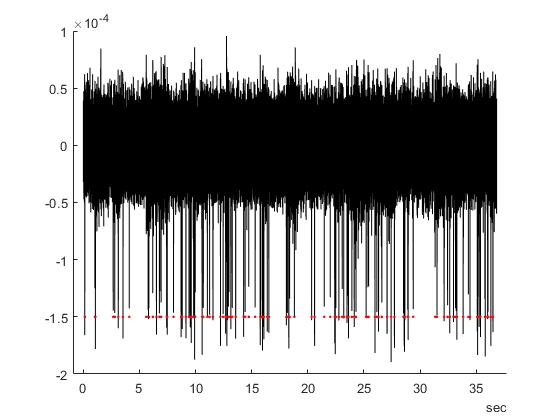

figure; hold on
plot(neural.Time,neural.spikes,'k')
scatter(neural.Time(locs(idx==2)),repmat(-1.5e-4,sum(idx==2),1),'.r')

Here we plot the PETH which is a histogram of spike counts aligned to a particular event. The event in this case, is the start of the recording. For the neuronal response to a particular stimulus, all timestamps need to be aligned with the time of the stimulus (trigger). Stimulus-triggered PETHs are also called PSTHs ([peri-stimulus time histograms](https://en.wikipedia.org/wiki/Peristimulus_time_histogram)).

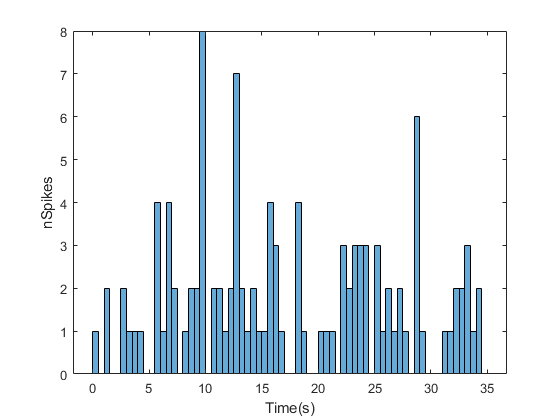

figure;
binSize = 0.5; % bin size in seconds
histogram(seconds(neural.Time(locs(idx==2))),0:0.5:35)
xlabel('Time(s)')
ylabel('nSpikes')

### 3.6 Calculating spectral estimates with the LFP

Spikes can tell us about the neural code as they are the output of neurons in the vicinity of the electrode. The low pass filtered data, the LFP, is also interesting because it captures all subthreshold potentials which did not exceed the threshold and contribute to spiking. Thus LFPs have information regarding the inputs to the neurons as well as an estimate of the global signal recorded between recording and reference electrodes.

To analyze the LFP, we move into the frequency domain where instead of analyzing time based events, we analyze the magnitude of oscillations at a certain frequency. Similar analyses are also performed for other types of neural signals such as [EEG](https://en.wikipedia.org/wiki/Electroencephalography)s and [ECoG](https://en.wikipedia.org/wiki/Electrocorticography).

#### 3.6.1 Preprocessing the data 

Before we start processing the LFPs, we need to do some pre-processing. It is important to remember that the LFP was filtered with a low pass filter at 200Hz. Since 200Hz is the highest frequency present in the signal, we can use a sampling frequency of 400Hz according to Nyquist Law. In reality we use a higher sampling frequency of 1000Hz. We begin by downsampling our original signal which was sampled at 40,000Hz. Timetables have several functions for [resampling and aggregating data](https://www.mathworks.com/help/matlab/matlab_prog/resample-and-aggregate-data-in-timetable.html).

resampleFs = 1000;
neural_lowPass = retime(neural,'regular','nearest',"SampleRate",resampleFs); % resample original times
neural_lowPass = removevars(neural_lowPass,{'spikes','raw'});

#### 3.6.2 Calculating the LFP power spectrum

Next, we need to convert the signal from the time domain to the frequency domain. For this, we use a technique called the [Fourier transform](https://www.mathworks.com/help/matlab/math/fourier-transforms.html). The simplest way to visualize the component frequencies in a signal is the amplitude spectrum which is a measure of the magnitude of the various constituent frequencies in a signal.

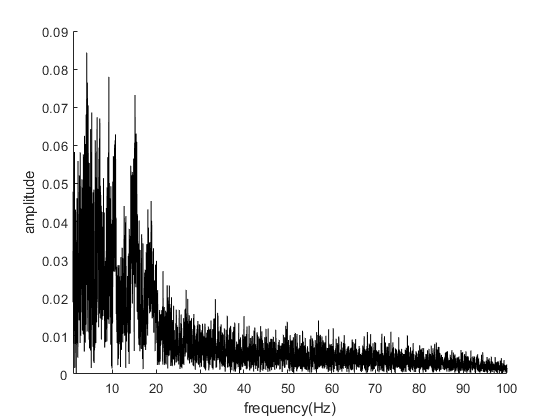

L = length(neural_lowPass.LFP); % length of signal
Y = abs(fft(neural_lowPass.LFP)); % compute the fast fourier transform and take absolute values
frange = linspace(0,1,L/2)*resampleFs/2; % compute frequency range upto Nyquist limit
fAmp = Y(1:floor(L/2)); % only use half the spectrum
figure; hold on
plot(frange,fAmp,'k') 
ylabel('amplitude')
xlabel('frequency(Hz)')
xlim([1 100]); % since this signal was low pass filtered at 200Hz

One of the most common spectral analyses is the computation of the [power spectrum](https://www.mathworks.com/help/signal/ref/pspectrum.html#mw_9274fcbe-75d0-491e-ac4b-0c8e06543935). The power spectrum is related to the amplitude spectrum.

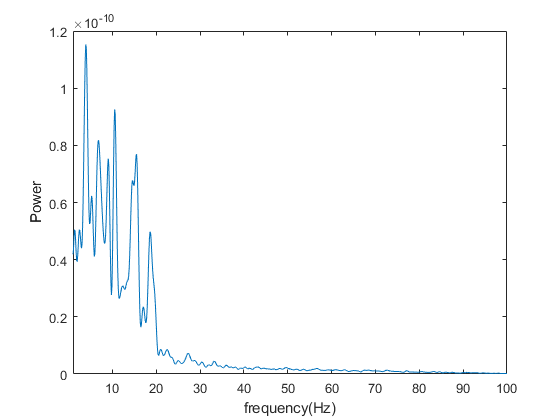

[pxx,f]=pspectrum(neural_lowPass.LFP,resampleFs,'Leakage',1);
figure;
plot(f,pxx);
ylabel('Power')
xlabel('frequency(Hz)')
xlim([1 100]); % since this signal was low pass filtered at 200Hz

#### 3.6.3 Calculating time frequency plots (spectrogram)

Just like the time domain, the frequency domain is often not stationary. Different frequencies can appear at different timepoints within a signal. A particularly good example of non-stationary frequency representations are obtained from [recordings of vocalizations](https://www.mathworks.com/help/signal/ug/extract-regions-of-interest-from-whale-song.html). To analyse the power spectrum in a time resolved fashion, compute the [spectrogram](https://www.mathworks.com/help/signal/ref/spectrogram.html) which returns the spectra in small windows along time. 

spWindow = 220; % spectrogram window (smaller windows yield greater temporal resolution)
figure; h1 = subplot(2,1,1);
spectrogram(neural_lowPass.LFP,spWindow,[],[],resampleFs,'yaxis'); % compute spectrogram
ylim([0 100])
h2 = subplot(2,1,2);
plot(neural_lowPass.Time,neural_lowPass.LFP,'k'); % show signal for comparison
xlim([min(neural_lowPass.Time) max(neural_lowPass.Time)]);
xlabel('Time(s)')

The next lines of code make the plots (spectrogram and signal) the same size (non-essential)

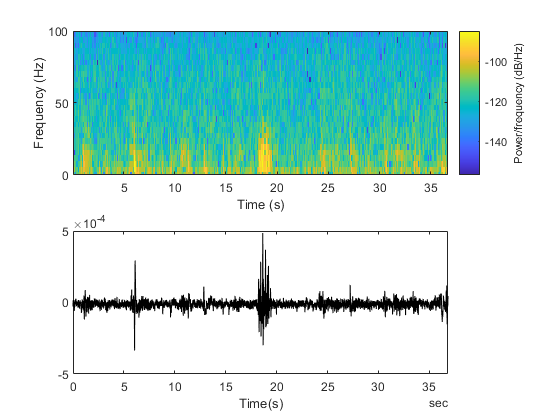

pos1 = get(h1,'Position');
pos2 = get(h2,'Position');
pos2(3)=pos1(3);
set(gca,'Position',pos2);

For more on basic [spectral analyses see here](https://www.mathworks.com/help/matlab/math/basic-spectral-analysis.html).

TODO: Compute the power spectrum and spectrogram using the SignalAnalyzer App.

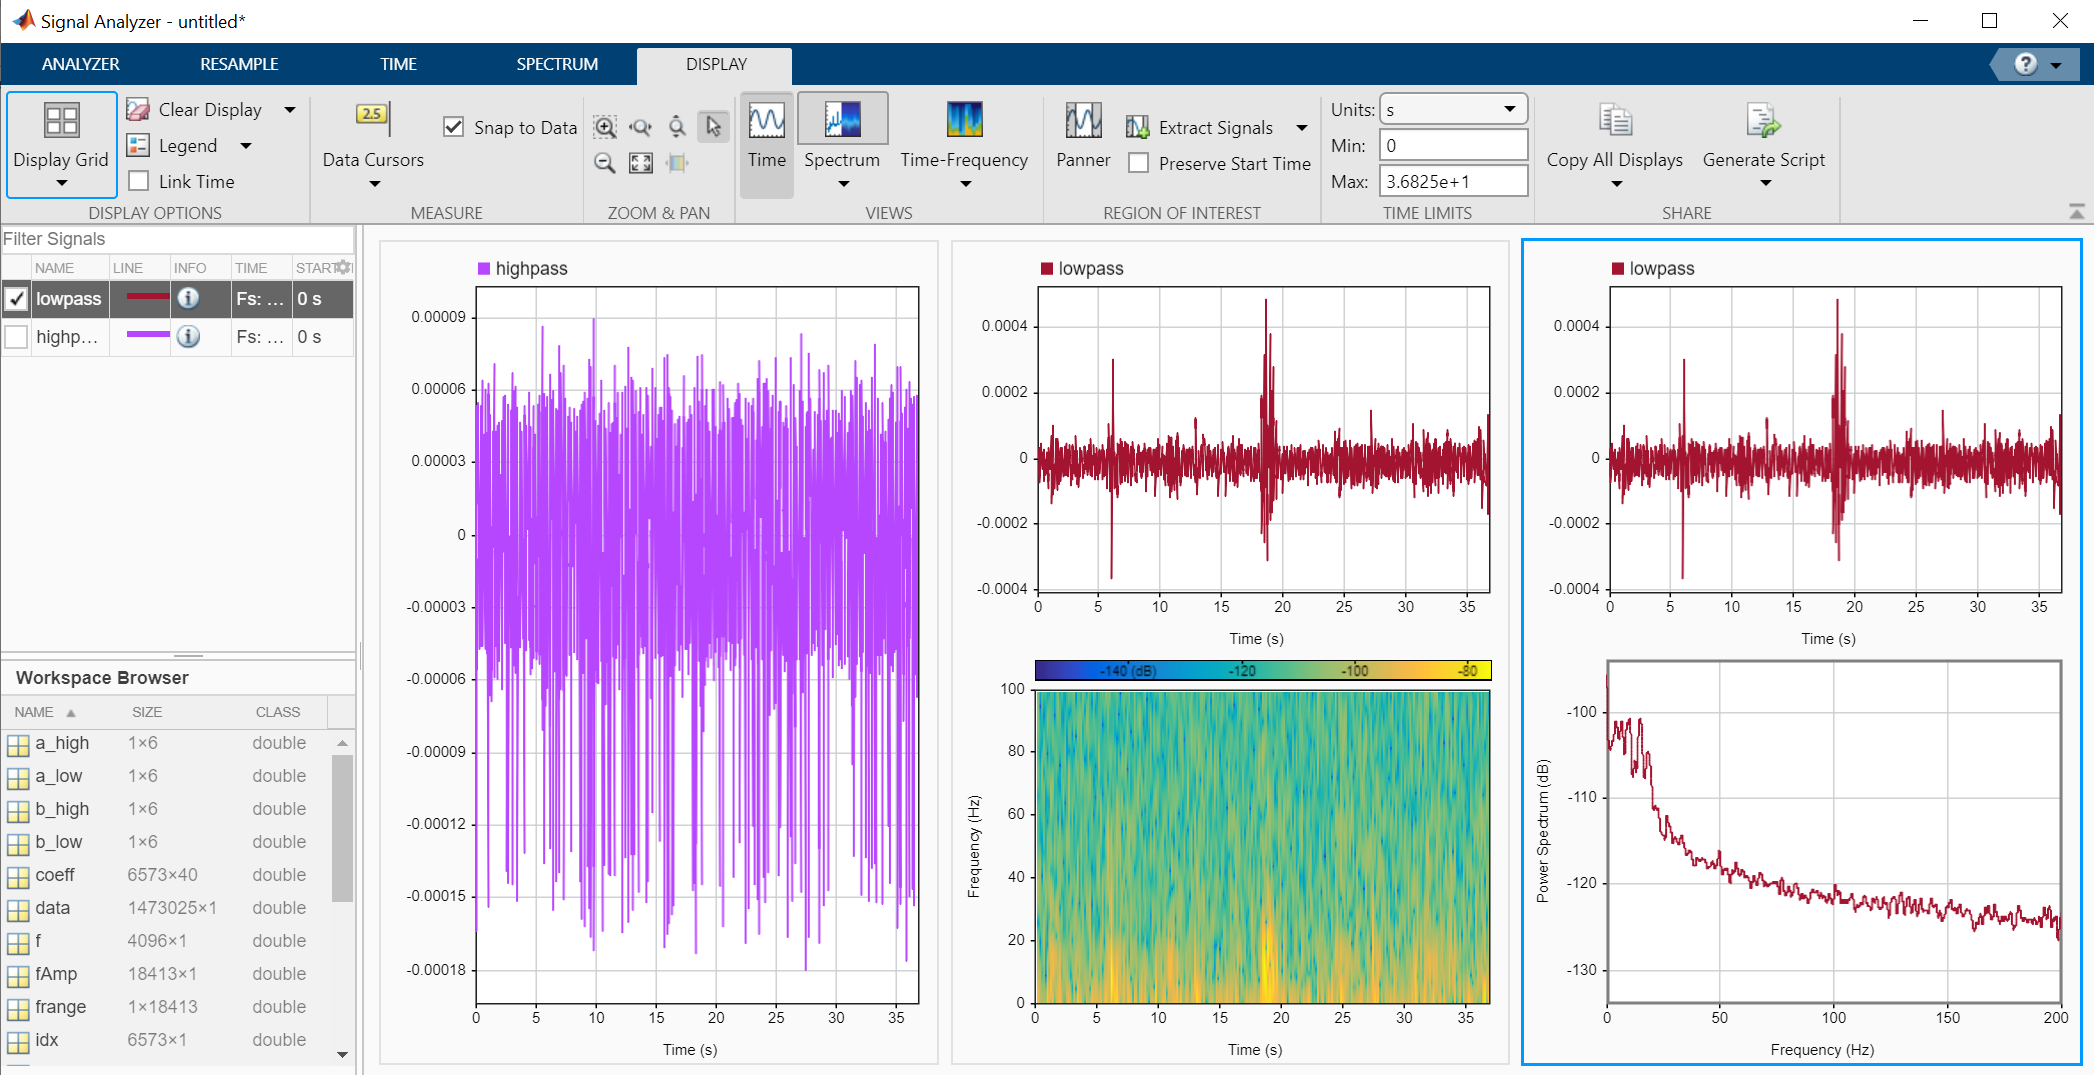

## References

[1] Eugene Izhikevich (2003). IEEE Transactions on Neural Networks (14). 1569-72. DOI: [10.1109/TNN.2003.820440](https://doi.org/10.1109/TNN.2003.820440)

[2] Hg Deviasse (licensed under [CC BY-SA 3.0 license](https://creativecommons.org/licenses/by-sa/3.0/))

[3] Obien et al. (2015), DOI: [https://doi.org/10.3389/fnins.2014.00423](https://doi.org/10.3389/fnins.2014.00423) (licensed under [CC BY-SA 4.0 license](https://creativecommons.org/licenses/by-sa/4.0/))

[4] Henze et al. (2000). DOI: [https://doi.org/10.1152/jn.2000.84.1.390](https://doi.org/10.1152/jn.2000.84.1.390)

[5] Buzsaki et al. (2012). DOI: [https://doi.org/10.1038/nrn3241](https://doi.org/10.1038/nrn3241)

[6] Chakrabarti, Schwarz (2018), DOI: [10.1038/s41467-018-06200-6](https://dx.doi.org/10.1038%2Fs41467-018-06200-6) (licensed under [CC BY-SA 4.0 license](https://creativecommons.org/licenses/by-sa/4.0/))

*Copyright 2020 The MathWorks, Inc*